# Spring-mass-damper impedance

Use the slider controls to change the system mass, spring stiffness, and damping while noting how the impdance changes.

clc
clear

f = 0.01:0.001:100;
w = f*2*pi;

m = 300;
k = 9000;
b =15630;


$$\zeta =\frac{b}{b_c }=\frac{b}{2\sqrt{\textrm{km}}}$$


zeta = b/(2*sqrt(k*m));
fprintf('Damping ratio, zeta [ ]: %g', zeta)

Damping ratio, zeta [ ]: 4.75606

The impedance can be defined as the complex sum of the resistance ($R$) and reactance ($X$).


$$Z = R + iX = b + i\left(\omega m - \frac{k}{\omega} \right)$$


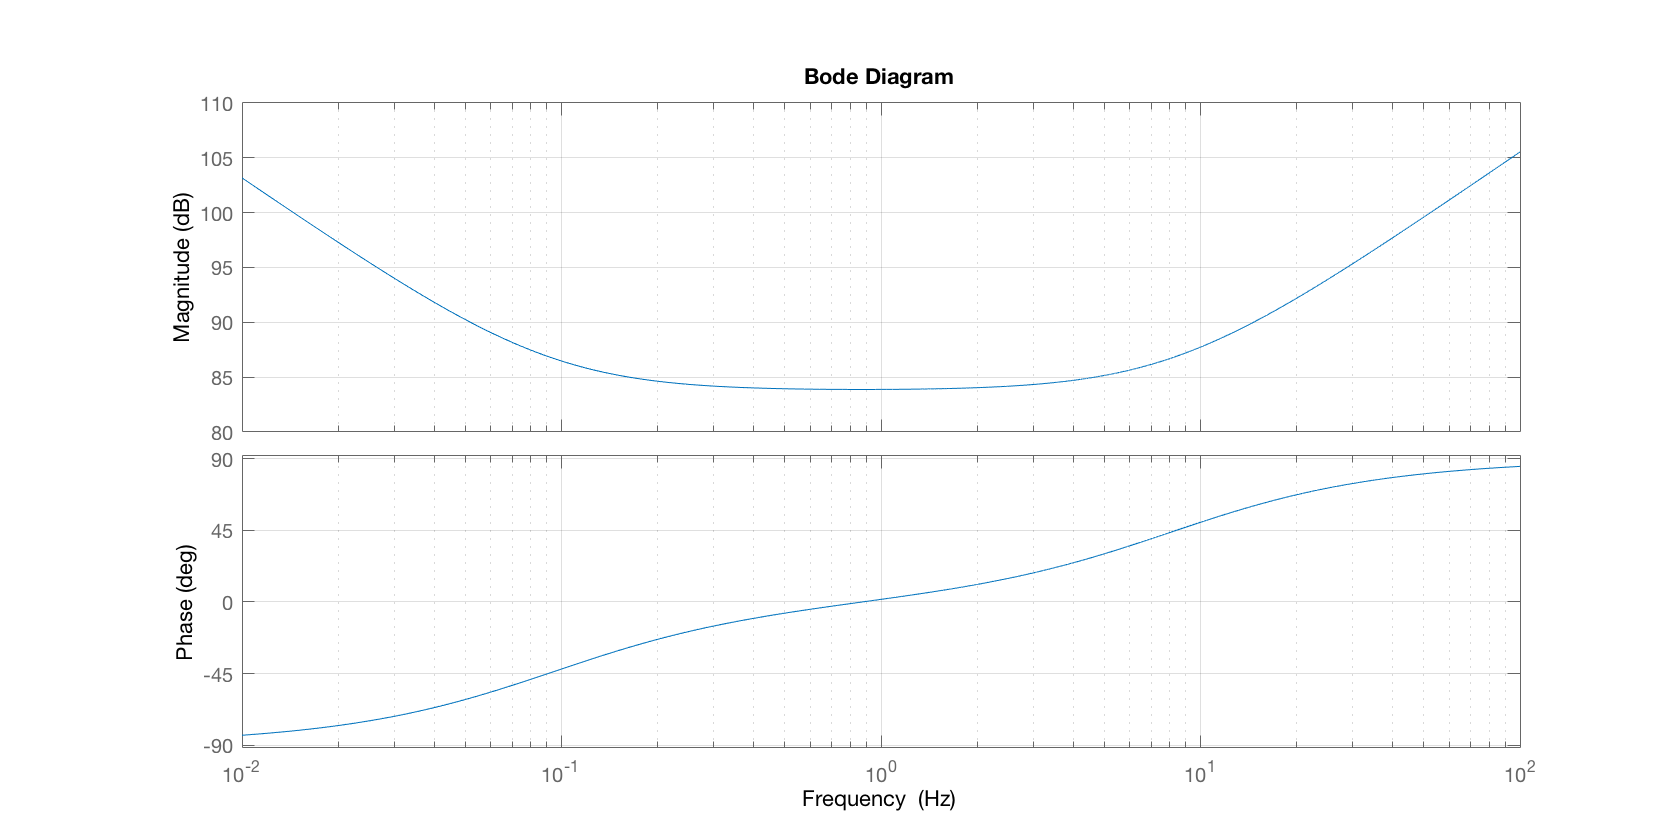


R = b;              % resistance
X = w*m - k./w;     % reactance
Z = R + 1i*X;       % impedance
sys_Z_FRD = frd(Z,w);

fig(1) = figure();
fig(1).Position = fig(1).Position .* [1 1 1.5 1];
h = bodeplot(sys_Z_FRD);
setoptions(h,'FreqUnits','Hz','Grid','on')

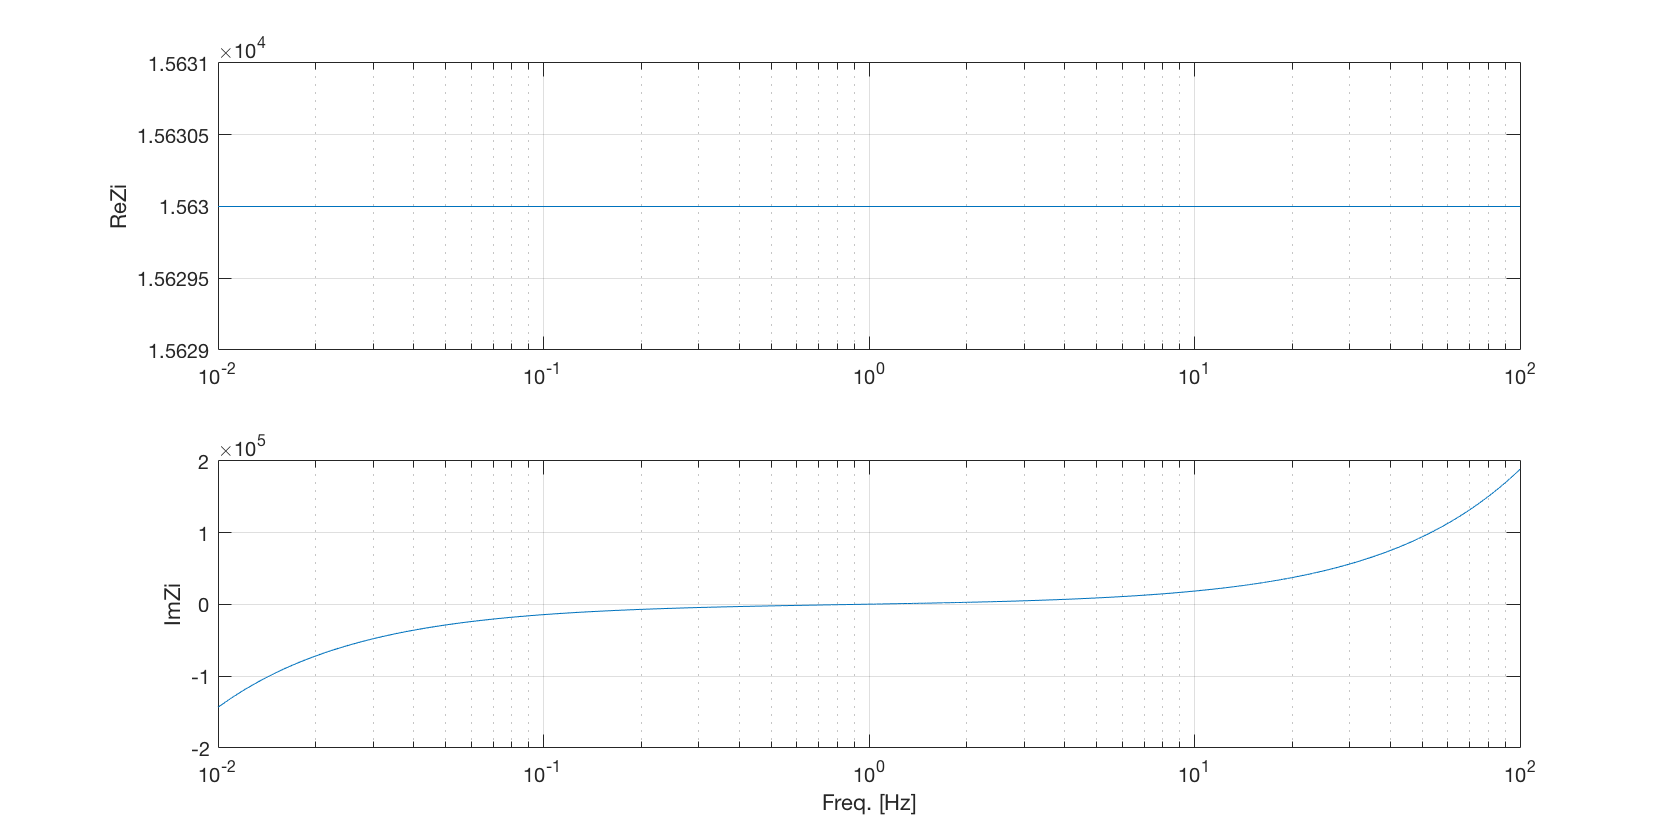


fig(2) = figure();
fig(2).Position = fig(2).Position .* [1 1 1.5 1];
title('Real and Imaginary parts of Zi')
ax(1) = subplot(2,1,1);
semilogx(f,real(Z))
ylabel('Re{Zi}')
grid on

ax(2) = subplot(2,1,2);
semilogx(f,imag(Z))
ylabel('Im{Zi}')
xlabel('Freq. [Hz]')
grid on

We can find the resonance as the frequency at which the imaginary part of the impedance is at a minimum.


$$\omega_n = \arg \min \Im \left\{ Z (\omega) \right\}$$


[~,ind] = min(abs(imag(Z)));
fn = f(ind)

fn = 0.8720

% Copyright 2020 National Technology & Engineering Solutions of Sandia,
% LLC (NTESS). Under the terms of Contract DE-NA0003525 with NTESS, the
% U.S. Government retains certain rights in this software.
%
% This file is part of fbWecCntrl.
%
%     fbWecCntrl is free software: you can redistribute it and/or
%     modify it under the terms of the GNU General Public License as
%     published by the Free Software Foundation, either version 3 of
%     the License, or (at your option) any later version.
%
%     fbWecCntrl is distributed in the hope that it will be useful, but
%     WITHOUT ANY WARRANTY; without even the implied warranty of
%     MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU
%     General Public License for more details.
%
%     You should have received a copy of the GNU General Public License
%     along with fbWecCntrl.  If not, see
%     <https://www.gnu.org/licenses/>.